clear variables

% 构建较为准确的降阶分析模型
sysFull = load("Data\SimulateData\sysFull.mat");
sysFull = sysFull.sys;
sysr = load("Data\SimulateData\sysflbt.mat");

sysr = sysr.sysflbt{2};

sysDis = c2d(sysr,0.02);

% 分析模型响应，并存储系统状态信息
u = @(t) [20*cos(t) * ones(1, 1);0*cos(t) * ones(1, 1);];
figure
opts = struct('InputFcn', u, 'TimeRange', 10,'StoreStates',1);
[t,y,info] = ml_dt_ss_simulate(sysDis, opts);

% Q: model error
% R: measurement error
% t = 0:0.02:10;

ureal = u(t');

Q = 0.01*eye(2);
R = 0.01*eye(2);

w = randn(length(t),2)*chol(Q);
v = randn(length(t),2)*chol(R);

w = w';
v = v';

A = sysDis.A;
B = sysDis.B;
C = sysDis.C;

duaStep = size(t,1);

state = zeros(3,duaStep);
outputMeasure = zeros(2,duaStep);
outputReal = zeros(2,duaStep);

for sample = 2:duaStep
    state(:,sample) = A*state(:,sample-1)+B*ureal(:,sample)+ B*w(:,sample);
    outputMeasure(:,sample) = C*state(:,sample);
    outputReal(:,sample) = C*state(:,sample) + v(:,sample);
end

sysKalman

[kalmf,L,~,Mx,Z] = kalman(sysDis,Q,R);

kalmf.InputGroup

ans = 包含以下字段的 struct :
     KnownInput: [1 2]
    Measurement: [3 4]



kalmf.OutputGroup

ans = 包含以下字段的 struct :
    OutputEstimate: [1 2]
     StateEstimate: [3 4 5]



out = lsim(kalmf,outputReal');

错误使用 DynamicSystem/lsim
当仿真对特定输入信号的响应时，输入数据 U 必须为矩阵，且其行数等于时间向量 T 中的采样数，列数等于输入通道数。


outEst = out';

figure;
plot(state(1,:));
hold on;
plot(outEst(4,:));

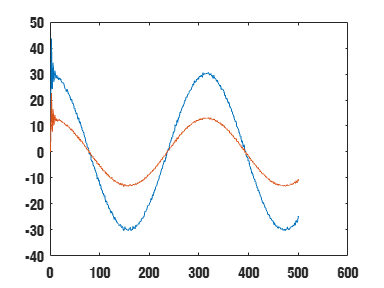

figure;
plot(outputReal(1,:));
hold on;
plot(outEst(1,:));

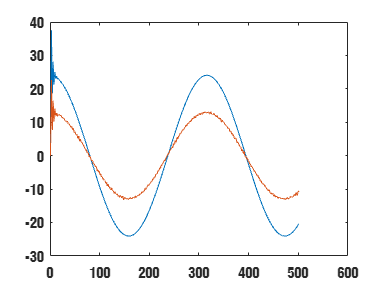

figure;
plot(y(2,:));
hold on;
plot(outEst(2,:));

O = obsv(sysDis.A,sysDis.C);
unobsv = length(sysDis.A) - rank(O)

figure;
plot((sysDis.C*outEst(3:5,:))')
figure;
plot(y(1:2,:)')